# 第3章 离散傅里叶变换

## 3.5 离散傅里叶变换的性质

### 3.5.9 圆周卷积及其与有限长序列的线性卷积关系

#### `Ch3_5_2`

`已知`$u\left(n\right)=\left\lbrack 0\;\;1\;\;2\;\;1\;\;0\right\rbrack$`和`$v\left(n\right)=\left\lbrack 0\;\;1\;\;0\;\;1\;\;0\right\rbrack$

`求：`

- $x\left(n\right)=u\left(\left(n-2\right)\right)$`和`$x\left(n\right)=u\left(\left(n+2\right)\right)$`的，`

- $u\left(n\right)$`和`$v\left(n\right)$`的``线性卷积`

- $u\left(n\right)$`和`$v\left(n\right)$`的圆周卷积`

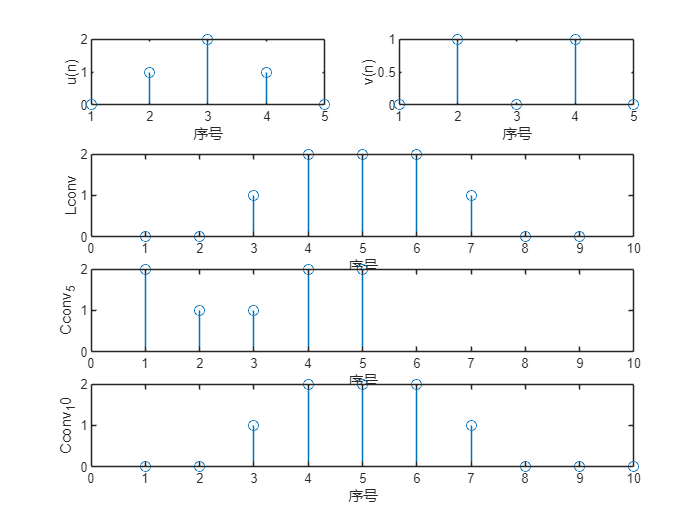

u = [0 1 2 1 0];
v = [0 1 0 1 0];
Lconv = conv(u,v);
Cconv_5 = cconv(u,v,5);
Cconv_10 = cconv(u,v,10);
x = circshift(u,2);  %循环右移2 x=u((n-2));
y = circshift(u,-2); %循环左移2 y=u((n+2));
subplot(4,2,1); stem(u); xlabel('序号'); ylabel('u(n)');
subplot(4,2,2); stem(v); xlabel('序号'); ylabel('v(n)');
subplot(4,2,[3, 4]); stem(Lconv); xlabel('序号'); ylabel('Lconv'); xlim([0 10]);
subplot(4,2,[5, 6]); stem(Cconv_5); xlabel('序号'); ylabel('Cconv_5'); xlim([0 10]);
subplot(4,2,[7, 8]); stem(Cconv_10); xlabel('序号'); ylabel('Cconv_10'); xlim([0 10]);